# Lecture #4: Linear versus circular convolution

We figured out by now that we can process ('filter') a signal through a system by convolving the input signal (speech, a car driving by, animal calls, music) with the impulse response of the system. 

The convolution theorem tells us at the same time, that we can as well just multiply the Fourier transforms of the signal with the Fourier transform of the impulse response (the transfer function):


$$y\left(t\right)=x\left(t\right)\ast h\left(t\right)\;\;\;\;\Leftrightarrow \;\;\;\;Y\left(\omega \right)=X\left(\omega \right)\cdot H\left(\omega \right)$$


Cool. Let's compare the convolution (`conv()` in MATLAB) with the multiplication in the frequency domain.

**Complete the code below to compute y(t) by**

- **Convolving the impulse response h with the input signal x**

- **Point-wise multiplication of the frequency transforms of x and h and then inverse Fourier transform into the time domain**

- **Plot both signals on top of each other**

clear all; close all;

% read the impulse response and the signal to be convolved
path2snd = ['..', filesep, 'sounds', filesep];
ir_fname = 'ir.wav';
h_info = audioinfo([path2snd, ir_fname]);
x_fname = 'x.wav';
x_info = audioinfo([path2snd, x_fname]);

% read audiofiles - and select only one channel!
h = audioread([path2snd, ir_fname]);
h=h(:,1);
x = audioread([path2snd, x_fname]);
x = x(:,1);

% match sample rates
if h_info.SampleRate ~= x_info.SampleRate
    resample(ir,x_info.SampleRate/h_info.SampleRate)
end

% listen to the signals (with the sample rate of x
%sound(h, x_info.SampleRate);
%pause
%sound(x, x_info.SampleRate);


% PLACE CONVOLUTION IN TIME DOMAIN HERE
y_conv = conv(x,h);

% Normalize amplitude
y_conv_norm = y_conv/max(y_conv)*.9;

% PLACE MULTIPLICATION IN FREQUENCY HERE
if length(h) > length(x)
    x = [x(:); zeros(length(h)-length(x),1)];
elseif length(x) > length(h)
    h = [h(:); zeros(length(x)-length(h),1)];
end

Y = fft(h).*fft(x)/(length(x)^2);

y_mult = real(ifft(Y));

% Normalize amplitude
y_mult_norm = y_mult/max(y_mult)*.9;

% PLOT BOTH RESULTS ON TOP OF EACH OTHER
plot(y_conv_norm,'Color','b'); hold on

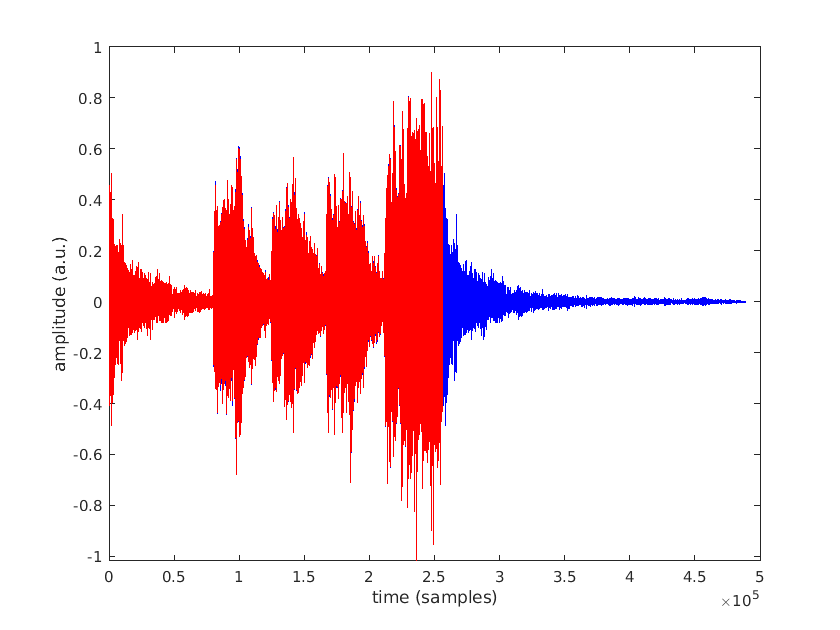

plot(y_mult_norm,'Color','r'); 
xlabel('time (samples)');
ylabel('amplitude (a.u.)');

% Listen to the sounds!
sound(y_conv_norm, x_info.SampleRate);
pause
sound(y_mult_norm, x_info.SampleRate);